# Getting Started with SNOBFit in MATLAB

**Barnaby Walker, James H. Bannock, Adrian M. Nightingale, and John C. de Mello**

In our article, 'Tuning Reaction Products by Constrainted Optimsation', we use the Stable Noisy Optimisation by Branch and Fit algorithm, or SNOBFit, to carry out chemical optimisations. The SNOBFit code provided by [Huyer and Neumaier](http://www.mat.univie.ac.at/~neum/software/snobfit/) is packaged with example scripts that lay out how to run an optimisation, and point out the parameters to change for different optimisations. For those with a some coding experience, this makes it straightforward to get an optimisation up an running. However, editing a script, or writing a new one, can be intimidating for first time users or those without much programming experience. This format also means that  you have to make a copy of the script for each optimisation you run, which can make it harder than necessary to keep track of changes and results.

To address these issues, and provide an easy-to-use interface for the SNOBFit algorithm, we developed a MATLAB class-based wrapper around the original SNOBFit code. The following tutorial will explain how to install and use this package.

This tutorial is designed for those with minimal experience in the MATLAB programming environment.

## INSTALLATION

The code can be installed by Downloading the provided zip file, extracting it, and copying the **'+snobfitclass'** folder into the folder where you want to use it. We recommend that you place this in your MATLAB directory, which is usually:

**    'C:\Users\{username}\Documents\Matlab'**

for Windows, or:

**    '~/Documents/MATLAB'**

for Mac or Linux.

Alternatively, you can get the latest version from our GitHub repository at [https://github.com/jdmgroup/snobfit-matlab-class.](https://github.com/jdmgroup/snobfit-matlab-class.) Just download (or clone) the repository into the folder you want to use the package from. While the latest code should be stable, we encourage further development of the interface.

## RUNNING AN OPTIMISATION

To use the package, you first need to import. If you put the package in your MATLAB folder you can do this simply by calling:

import snobfitclass.*

Otherwise, you will have to make sure that you are in the same folder as the package.

## Creating the SNOBFit Object

The class-based wrapper that we have written is based around a SNOBFit optimisation object. This object has various settings that you can change to set up your experiment, will run the actual optimisation, and will store all of your results.

The first thing you need to do to use it, is create the object:

snobfit_object = snobfitclass.snobclass()

User must enter function and setup values!


snobfit_object =   snobclass with properties:

             name: 'untitled'
              fcn: 'none'
    constraintFcn: 'none'
           linked: 0
      constrained: 0
       continuing: 0
            combo: 0
           status: []
        minimised: []
            fbest: []
            xbest: []
            ncall: 100
      termination: 'minimised'


Here you can see some of the properties available to you to set up your experiment.

The very least that you have to set before running your optimisation is the name of the function that you want to optimise. In this example we will be optimising the Branin function, which has the equation:


$$f\left(x_1 ,x_2 \right)={\left(x_2 -\frac{5\ldotp 1x_1^2 }{4\pi^2 }+\frac{5x_1 }{\pi }\right)}^2 +\left(10-\frac{10}{8\pi }\right)\mathrm{cos}\left(x_1 \right)+10$$


In this optimisation we are trying to minimise the value of $f\left(x_1 ,x_2 \right)$ by calculating it for different values of $x_1$ and $x_2$ recommended by the SNOBFit algorithm.

In our example, we have given this function the name 'bra':

snobfit_object.fcn = 'bra'

SNOBFIT experiment has been created!


snobfit_object =   snobclass with properties:

             name: 'untitled'
              fcn: 'bra'
    constraintFcn: 'none'
           linked: 0
      constrained: 0
       continuing: 0
            combo: 0
           status: 'initialised'
        minimised: 0
            fbest: []
            xbest: []
            ncall: 100
      termination: 'minimised'


While you can go ahead and start your experiment now, it is also sensible to give your experiment a name:

snobfit_object.name = 'my_first_snobfit'

snobfit_object =   snobclass with properties:

             name: 'my_first_snobfit'
              fcn: 'bra'
    constraintFcn: 'none'
           linked: 0
      constrained: 0
       continuing: 0
            combo: 0
           status: 'initialised'
        minimised: 0
            fbest: []
            xbest: []
            ncall: 100
      termination: 'minimised'


The SNOBFit object uses this name when saving the results of your experiment, as well as for storing information that it uses as it runs.

You can see where your results will be saved by accessing the filepath property:

snobfit_object.filepath

ans = 'C:\Users\jdmgroup\Documents\MATLAB\SNOBFIT'

You can also change this property by assigning it a new file path to save to.

Another important property to set before running your optimisation is the maximum number of function calls to try before ending, even if a minimum hasn't been found. In this case, we'll set it to 50:

snobfit_object.ncall = 50

snobfit_object =   snobclass with properties:

             name: 'my_first_snobfit'
              fcn: 'bra'
    constraintFcn: 'none'
           linked: 0
      constrained: 0
       continuing: 0
            combo: 0
           status: 'initialised'
        minimised: 0
            fbest: []
            xbest: []
            ncall: 50
      termination: 'minimised'


At this point, we can run our first SNOBFit optimisation:

SNOBFIT experiment is running...
ncall:	1 to 6
xbest:	-3.540000, 14.565000
fbest:	2.871338
ncall:	7 to 12
xbest:	-3.540000, 14.565000
fbest:	2.871338
ncall:	13 to 18
xbest:	-3.540000, 14.565000
fbest:	2.871338
ncall:	19 to 24
xbest:	-2.640000, 11.250000
fbest:	1.602584
ncall:	25 to 30
xbest:	-3.225000, 12.435000
fbest:	0.432977
ncall:	31 to 36
xbest:	-3.225000, 12.435000
fbest:	0.432977
ncall:	37 to 42
xbest:	-3.150000, 12.300000
fbest:	0.398250
SNOBFIT experiment has finished, and a minimum was found!


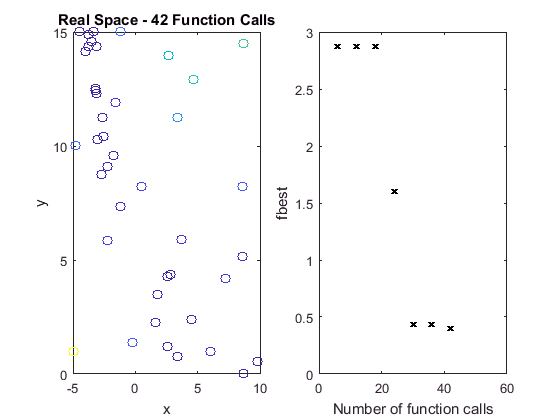

snobfit_object.startExp;

As the optimisation runs, the object prints out the current best function value and the location of that value. It also shows a scatter plot of all the points shown so far, next to a plot of the best function value against the number of function calls. This can help you to visualise your results as the optimisation proceeds, and see if everything is proceeding as it should be.

In this case, our function has a minimum that can be worked out analytically. This is 0.39788

## ACCESSING YOUR RESULTS

After your optimisation has run, you can access the results directly through the SNOBFit object itself.

To see what the best function value found was:

snobfit_object.fbest

ans = 0.3982

And the location of the best point:

snobfit_object.xbest

ans =    -3.1500   12.3000


For this example we can compare these results to the true minimum of the function, because we know what it should be. The true minimum is 0.3979 at $\left(x_1 ,x_2 \right)=\left(9\ldotp 4248,2\ldotp 4750\right)\text{ }\mathrm{or}\text{ }\left(-3\ldotp 1416,12\ldotp 2750\right)\text{ }\mathrm{or}\text{ }\left(3\ldotp 1416,2\ldotp 2750\right)$.

This result is very close, but not at the true minimum. This is because the SNOBFit object has been set to stop within a particular threshold of the minimum, in this case 0.001. This threshold can be viewed or changed:

snobfit_object.threshold

ans = 1.0000e-03

The SNOBFit object knows the minimum to aim for in this example because we have already provided it:

snobfit_object.fglob

ans = 0.3979

If you do not give this to the SNOBFit object, it will try to get the objective function value to within the threshold of zero.

This is just one termination condition that is available. For a description of the other termination conditions, and how to set them up, please see the 'Defining an Optimisation' tutorial.

You can also see all of the parameters that the optimisation tried:

snobfit_object.x

ans =     7.2150    4.1700
    8.5800    8.2050
   -3.0900   14.3700
    8.7000   14.4750
    4.4850    2.3700
   -3.5400   14.5650
   -4.9800    1.0050
   -1.1700    7.3500
    3.4200   11.2350
   -0.2250    1.3650


And all of the function values that these gave:

snobfit_object.f

ans =    24.3007
   43.9527
    5.3331
  160.1509
    8.6626
    2.8713
  272.5464
   14.2209
   84.8034
   44.3565


Perhaps more importantly, this means that you can make your own plots from the data. For instance, if we wanted to recreate the scatter plot for our optimisation above, but this time make the colour of the circle represent the function value, and change how it looks a bit:

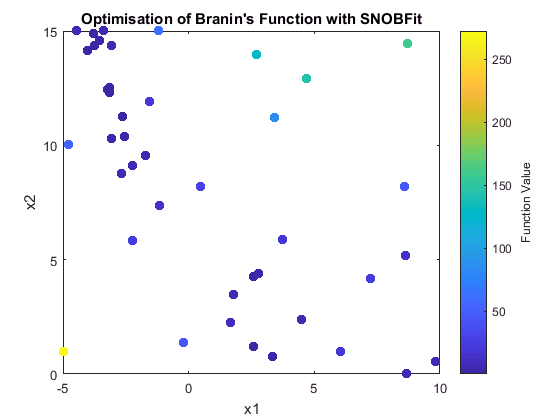

figure
scatter(snobfit_object.x(:,1), snobfit_object.x(:,2), 50, snobfit_object.f, 'filled')
c = colorbar;
box on
xlabel('x1')
ylabel('x2')
title('Optimisation of Branin''s Function with SNOBFit')
ylabel(c, 'Function Value')

Or we can make a completely different plot with the data. For instance, you might want to fit a surface to the data points that the optimisation tried (this requires you to have the MATLAB Curve Fitting Toolbox installed):

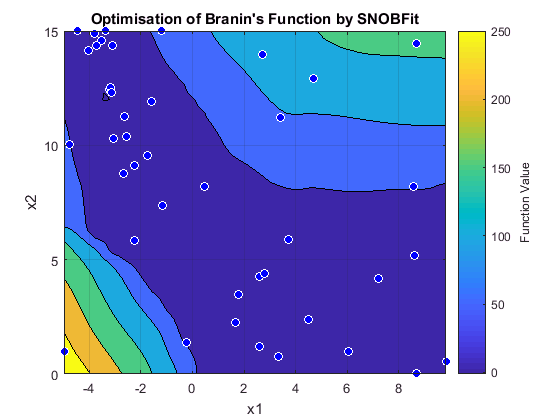

fitobject = fit(snobfit_object.x, snobfit_object.f, 'Lowess', 'Normalize', 'on');
plot(fitobject, snobfit_object.x, snobfit_object.f, 'Style', 'Contour');
c = colorbar;
xlabel('x1')
ylabel('x2')
ylabel(c, 'Function Value')
title('Optimisation of Branin''s Function by SNOBFit')

As well as storing your results on the SNOBFit object itself, the object also saves a copy of itself in a .mat file and the results and a summary of the optimisation in comma-separated (.csv) files in the Results folder on the object's filepath. This means that you can load the SNOBFit object back into MATLAB from the .mat file to access the results or continue the optimisation, even if your computer turns off without you manually saving anything. Saving the results as .csv files also means that you can move these results to any computer and analyse them using whatever analysis software you prefer, such as Python or Excel.